# Simulación de Brazos Robóticos

# Cinemática, Dinámica y Control

Dificultad: Normal (Básico, Teoría)

## Teoría

- Un sistema robótico de articulaciones rotacionales se modela por el siguiente sistema diferencial no lineal

$D(\theta(t))\ddot{\theta}(t)+H(\theta(t),\dot{\theta}(t))\dot{\theta}(t)+g(\theta(t))= T(t)$, 

            donde $\theta(t)$ es el ángulo de la articulación, $T(t)$ es el torque aplicado a la articulación, $D(\theta(t))$ es la matriz de masa o inercia, $H(\theta(t),\dot{\theta}(t))$ representa las fuerzas centrífugas y de Coriolis y $g(\theta(t))$ es el vector que incluye los términos gravitatorios.

- **Cinemática:** La entrada del sistema es el ángulo $\theta(t)$ y sus derivadas. Se calcula el torque necesario para obtener dichos ángulos y derivadas y se simula. Es un sistema ideal que no depende de los valores de $D(\theta(t))$, $H(\theta(t),\dot{\theta}(t))$ y $g(\theta(t))$.

- **Dinámica:** La entrada es el torque $T(t)$ sobre la articulación. En función de la ecuación, la articulación rota un ángulo $\theta(t)$ y derivadas. Es el sistema real y depende de los valores de $D(\theta(t))$, $H(\theta(t),\dot{\theta}(t))$ y $g(\theta(t))$

- **Dinámica con control realimentado:** La entrada es torque $T(t)$ y se realimenta en lazo cerrado el valor de la $\theta(t)$ real. Por medio de un controlador se actua con el torque $T(t)$ adecuado para obtener el ángulo $\theta(t)$ deseado. Se suele usar dos lazos, uno interno derivativo y uno externo proporcional. En la gráfica, $u= T(t)$, $y_m=\theta_{medido}(t)$ y $r=\theta_{referencia}$ . El controlador $C1$ es proporcional y el $C2$ es derivativo. Es el sistema real de un robot, donde cada articulación es controlada por un controlador P-D.

## 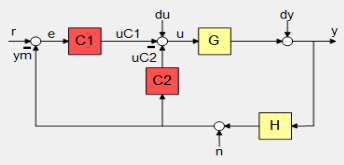

## Simulación de un sistema con *SimScape* *Multibody* (péndulo doble)

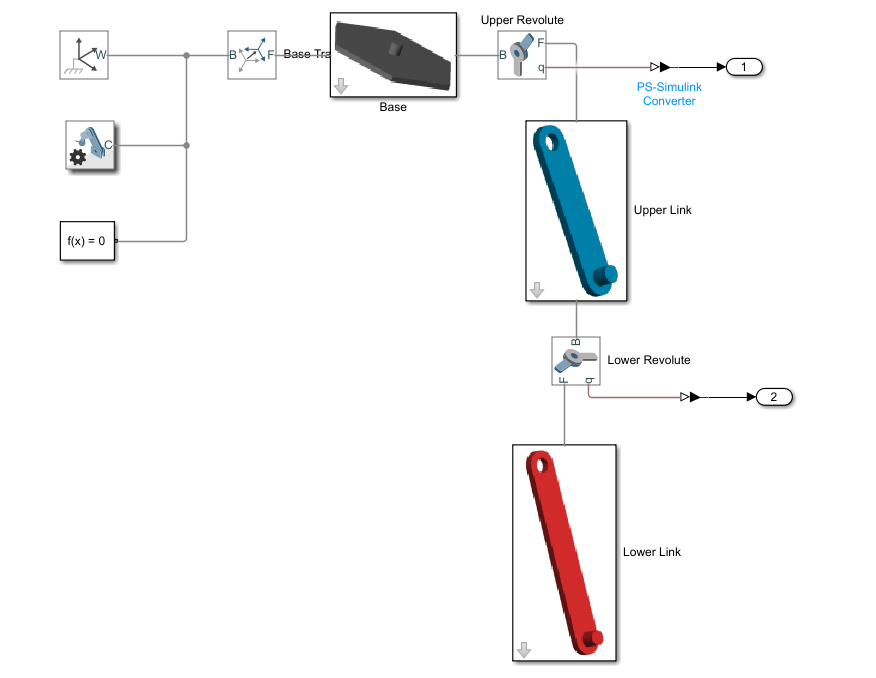

### Descripción del sistema:

- El sistema tiene dos articulaciones rotacionales.

- La estación no tiene entradas y tiene dos salidas, la posición de cada uno de las articulaciones rotaciones.

- El sistema es no lineal y su linealización depende de las posiciones iniciales de las articulaciones, y de los parámetros mecánicos de las articulaciones y brazos. 

### Articulación

- La articulación puede tener como entrada el torque o la posición deseada. En este caso no hay entrada.

- La articulación puede tener de salida la posición, velocidad o el torque obtenido por el efecto de la entrada.

- Los parámetros de la articulación son $B$ (coeficiente de fricción viscoso), $K$(constante del muelle), y el punto de equilibrio desde el que se parte $theta0$. También se pueden añadir restricciones de posición.

### Brazos robóticos

- Los brazos robóticos reflejan las propiedades mecánicas de cada brazo, tanto visuales como de inercia.

#### Posición inicial para los dos ejes del sistema (determina el punto de equilibrio):

- Sistema estable: $theta0=[\theta, -\theta]$.

- Sistema inestable (péndulo invertido): $theta0= [\theta,180-\theta]$.

deg= pi/180; % paso de grados a radianes
thetaeq= 170;
theta0= [thetaeq, 180- thetaeq]*deg;

#### Constantes de los muelles de las articulaciones

- Una articulación rígida tiene una $K$muy grande, y una libre una $K=0$.

K= [0,0];

#### Coeficiente de amortiguamiento en articulaciones

- Una articulación con rozamiento tiene una $B$ grande, y sin rozamiento $B=0$.

B= [1, 1]*1e-2;

#### Simulación del sistema desde una posición inicial.

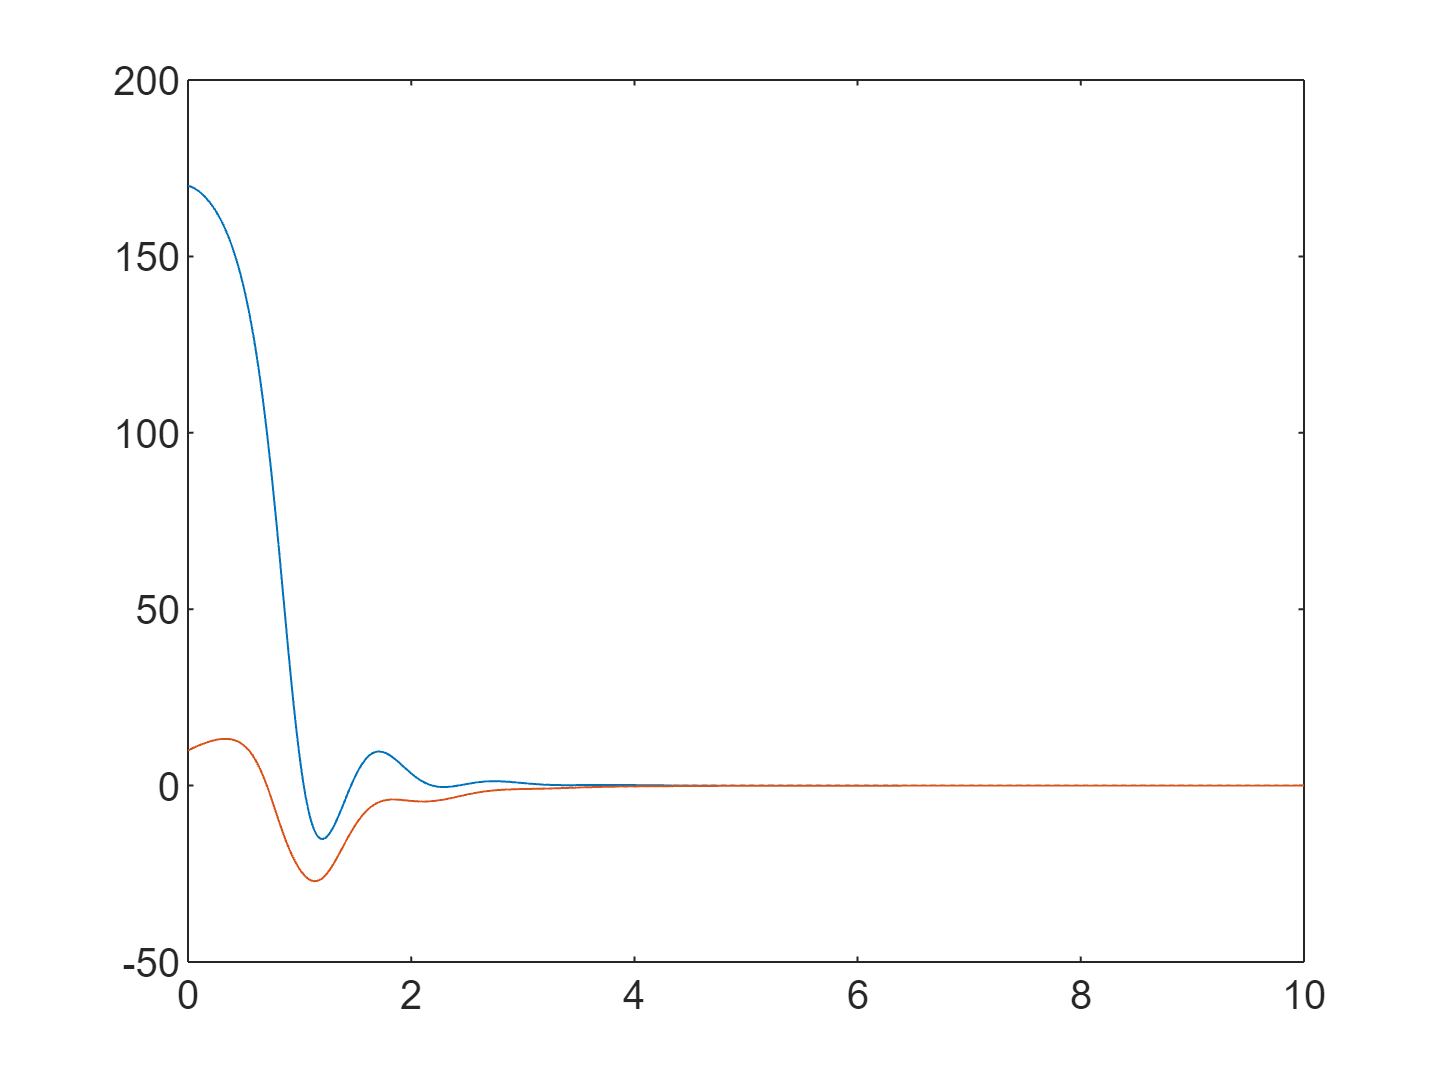


Estacion= 'T15S1_Doble_Pendulo';
nPts= 1e3;
tend= 10;
t= linspace(0,tend,nPts)';
open_system(Estacion)
sol= sim(Estacion,t);
q= sol.yout;
tout= sol.tout;
plot(tout, q/deg)

## Planta cinemática 

- La entrada del sistema es el ángulo $\theta(t)$ y sus derivadas. Se calcula el par necesario para obtener dichos ángulos y derivadas y se simula. Es un sistema ideal que no depende de los valores de $D(\theta(t))$, $H(\theta(t),\dot{\theta}(t))$ y $g(\theta(t))$, ya que se calcula el torque necesario para conseguir el $\theta(t)$ a partir de la ecuación.

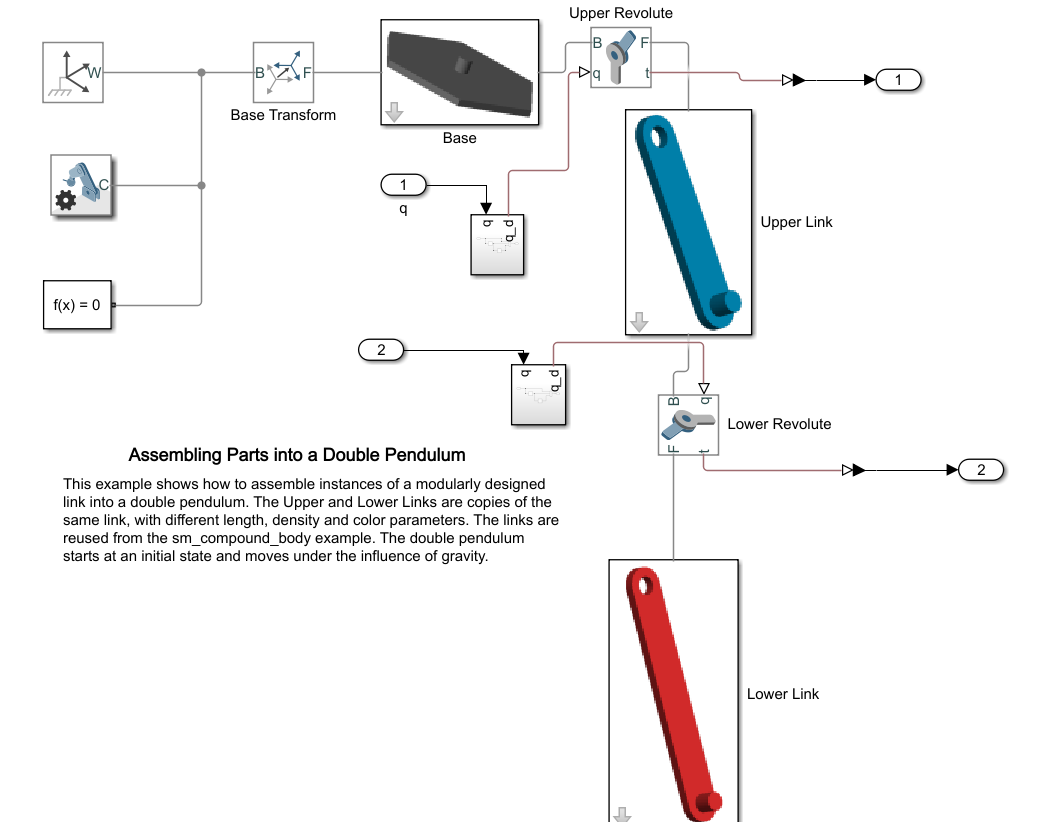

- Entrada de $\theta$ y derivadas: Se convierte la señal de simulink en tres de SimScape, $\theta$, $\dot{\theta}$ y $\ddot{\theta}$ .

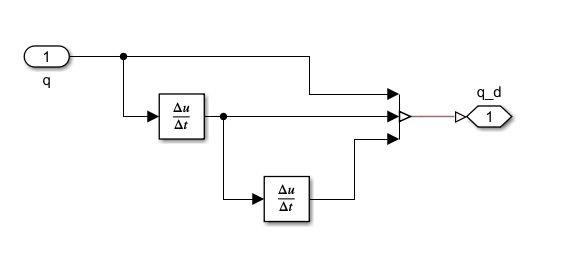

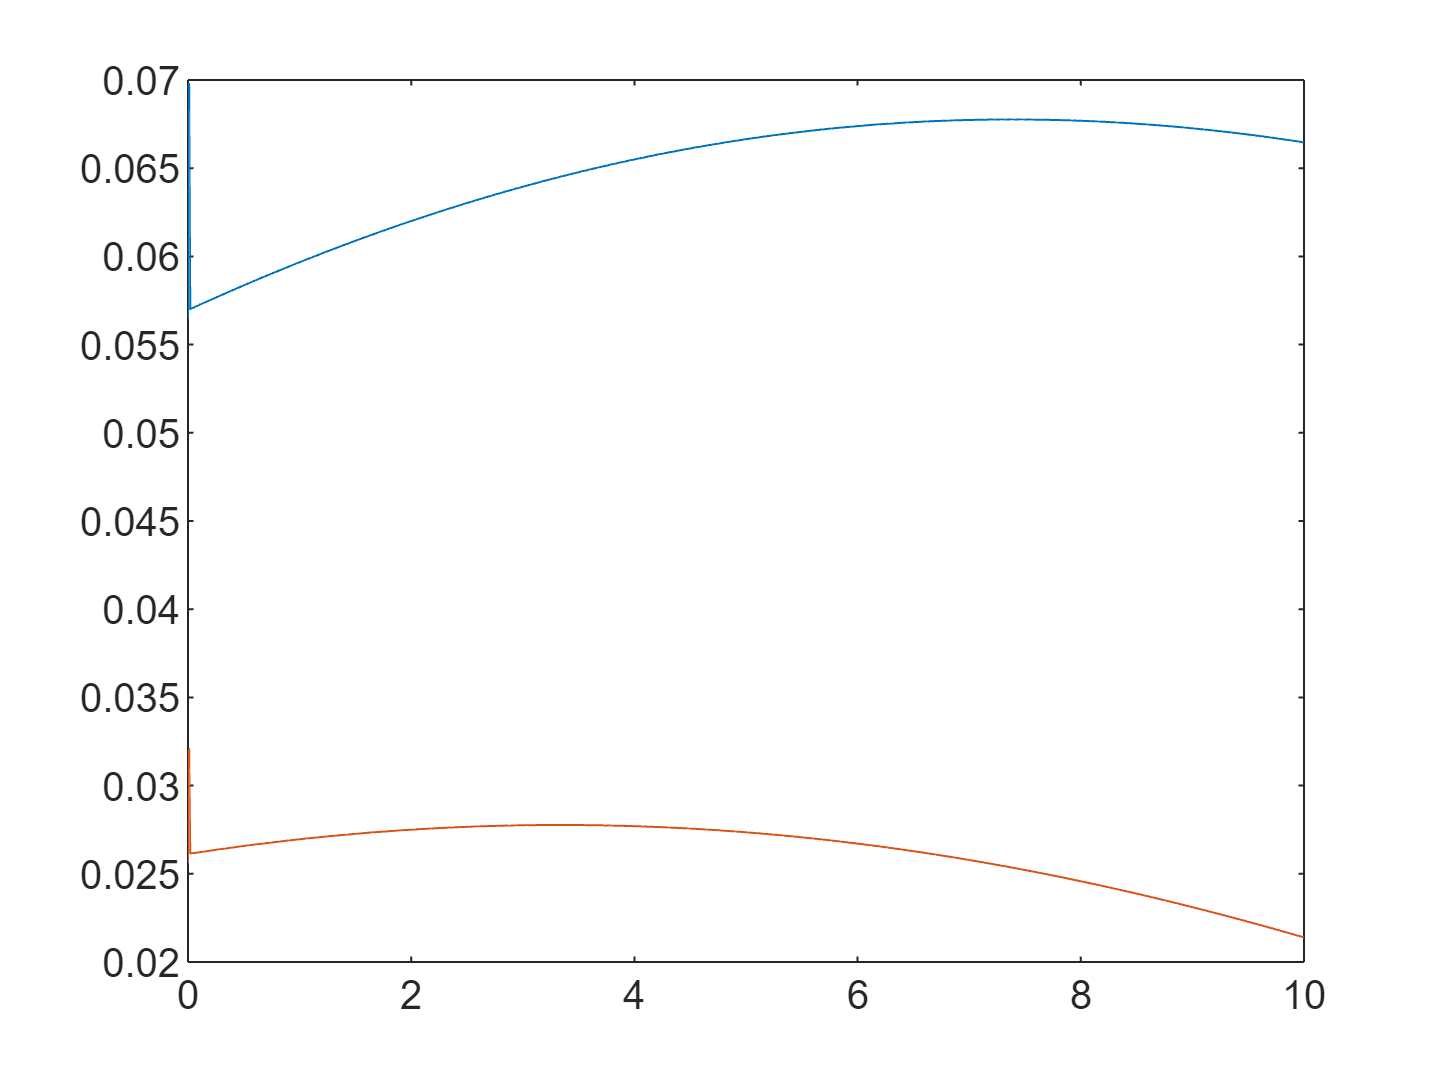

deg= pi/180; % paso de grados a radianes
Estacion= 'T15S2_Cinematica';
nPts= 1e3;
tend= 10;
t= linspace(0,tend,nPts)';

% Ángulo inicial y parámetros del sistema
theta0= [40, 30]*deg;
K= [0,0];
B= [1, 1]*1e-2;

% Entrada al sistema
theta1= linspace(theta0(1),theta0(1)+30*deg,nPts)';
theta2= linspace(theta0(2),theta0(2)+30*deg,nPts)';
open_system(Estacion)
sol= sim(Estacion,t,[],[t, theta1, theta2]);
% Salida del sistema
T= sol.yout;
tout= sol.tout;
plot(tout, T)

## Planta dinámica

- La entrada es el torque $T(t)$ sobre la articulación. En función de la ecuación la articulación rota un ángulo $\theta(t)$ y derivadas. Es el sistema real que depende de los valores de $D(\theta(t))$, $H(\theta(t),\dot{\theta}(t))$ y $g(\theta(t))$.

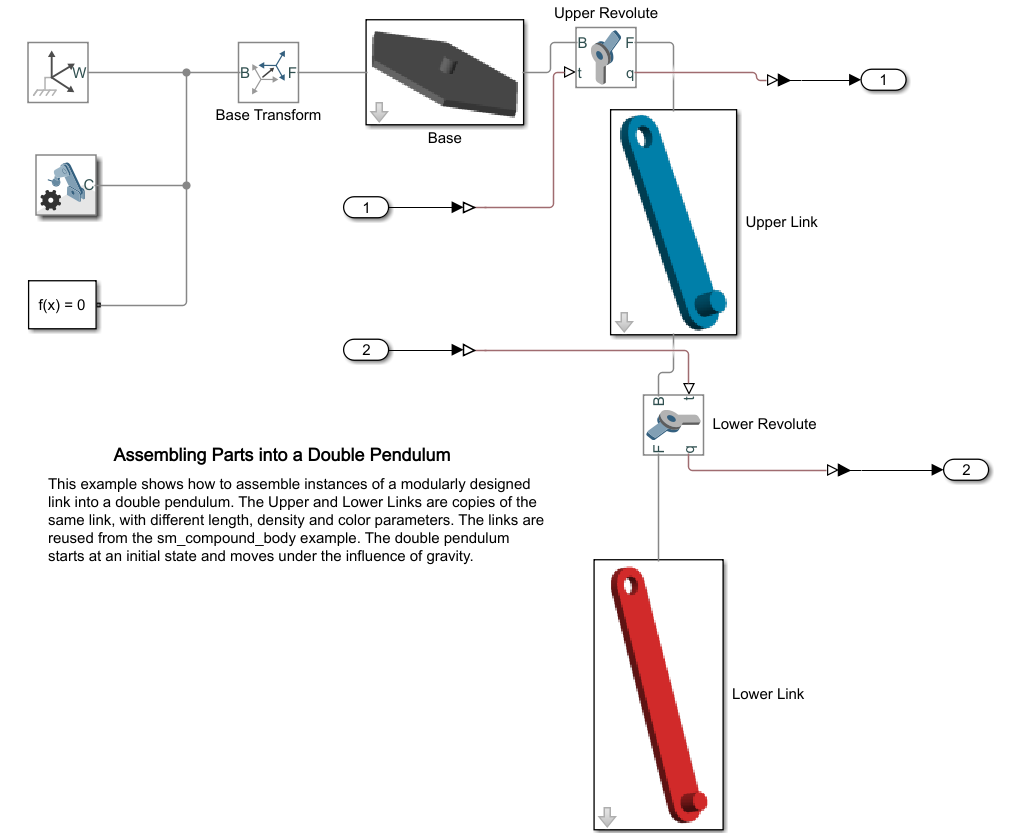

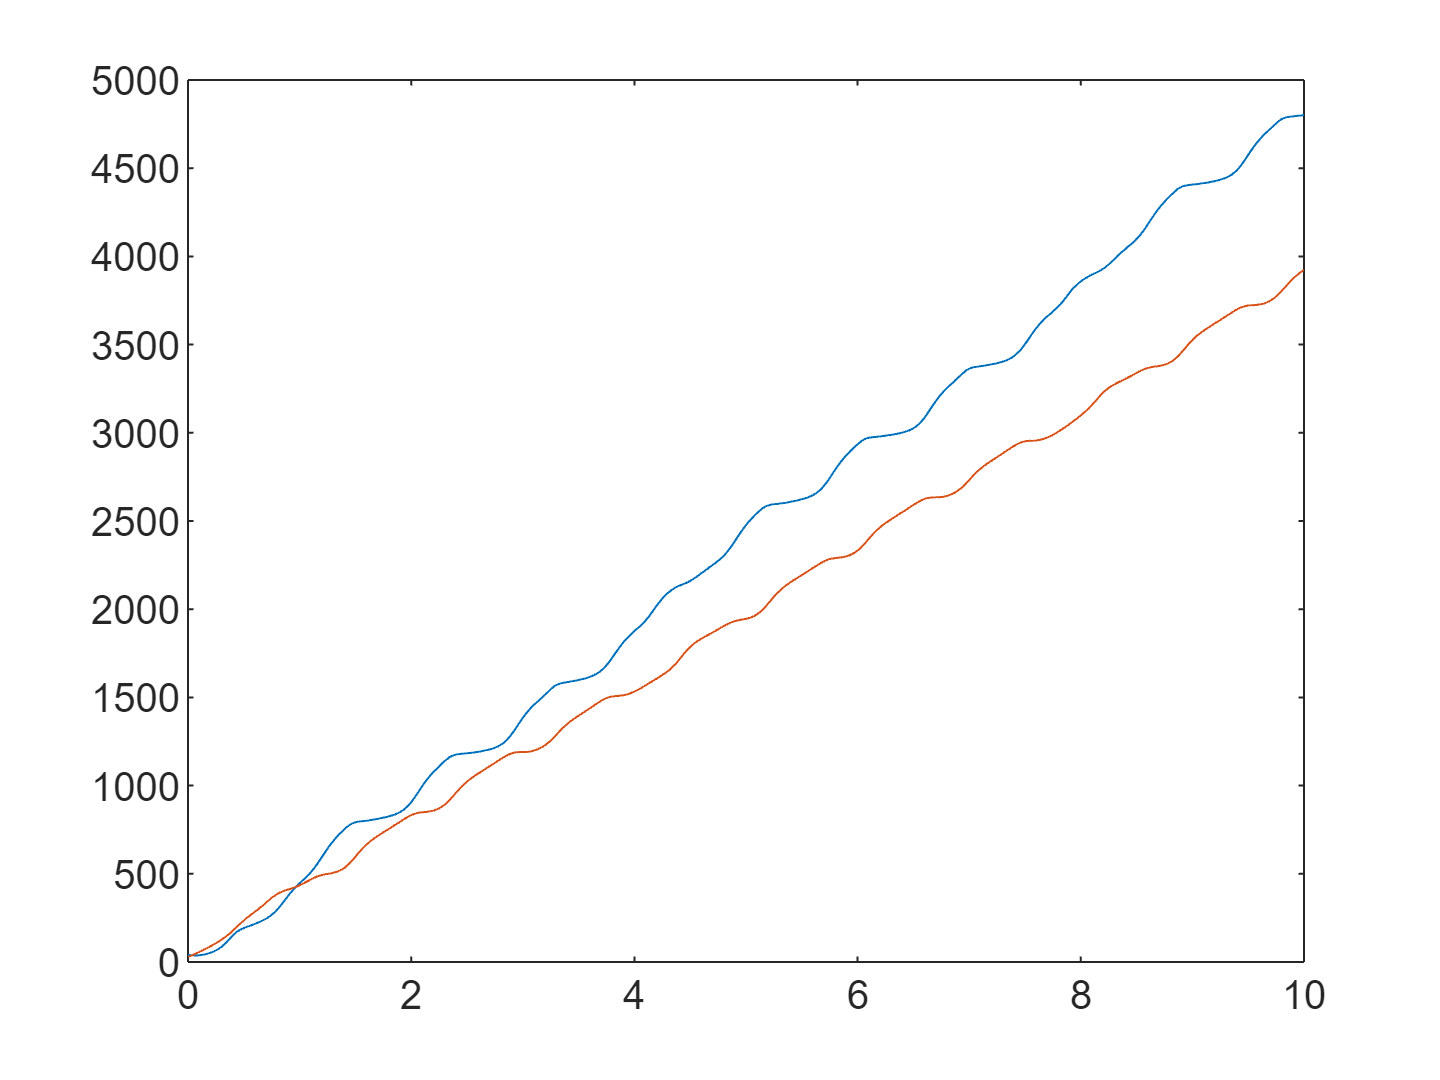

deg= pi/180; % paso de grados a radianes
Estacion= 'T15S3_Dinamica';
open(Estacion)
nPts= 1e3;
tend= 10;
t= linspace(0,tend,nPts)';

% Ángulo inicial y parámetros del sistema
theta0= [40, 30]*deg;
K= [0,0];
B= [1, 1]*1e-2;

T1= 1e-1*ones(nPts,1);
T2= 1e-1*ones(nPts,1);
open_system(Estacion)
sol= sim(Estacion,t,[],[t, T1, T2]);
q= sol.yout;
tout= sol.tout;
plot(tout, q/deg)

## Planta dinámica con realimentación

- La entrada es torque $T(t)$ y se realimenta en lazo cerrado el valor de la $\theta(t)$ deseado. Por medio de un controlador se actua con el torque $T(t)$ adecuado para obtener el ángulo $\theta(t)$ deseado. Se suele usar dos lazos, uno interno derivativo y uno externo integral. En la gráfica, $u= T(t)$, $y_m=\theta_{medido}(t)$ y $r=\theta_{referencia}$ . Es el sistema real de un robot.

## 

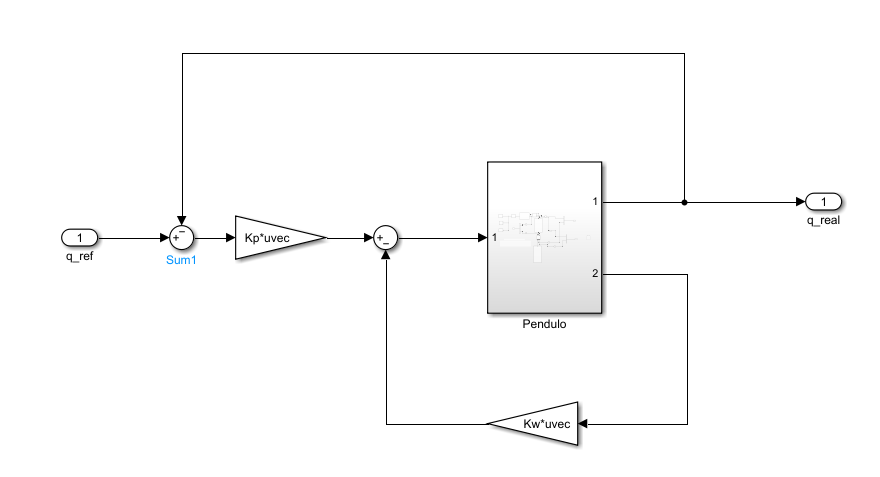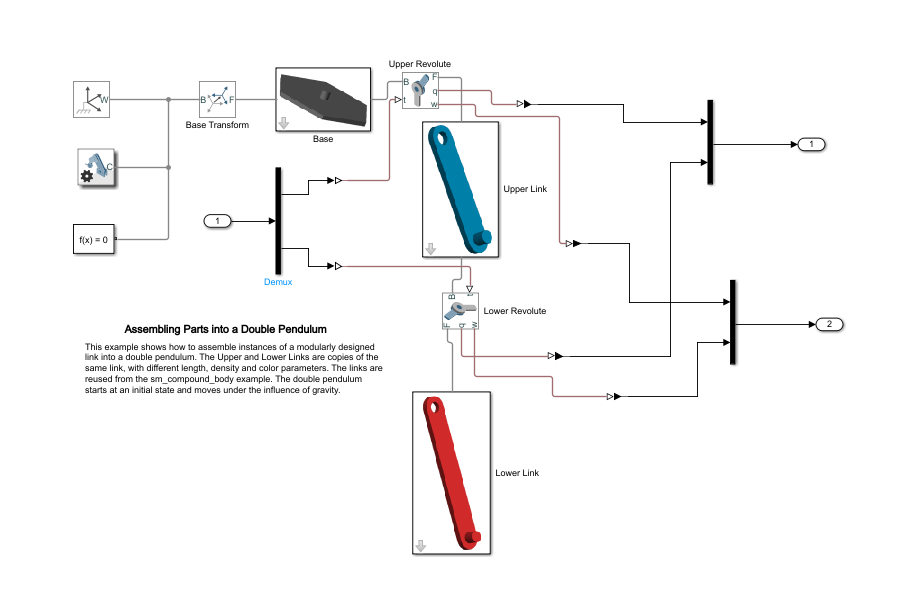

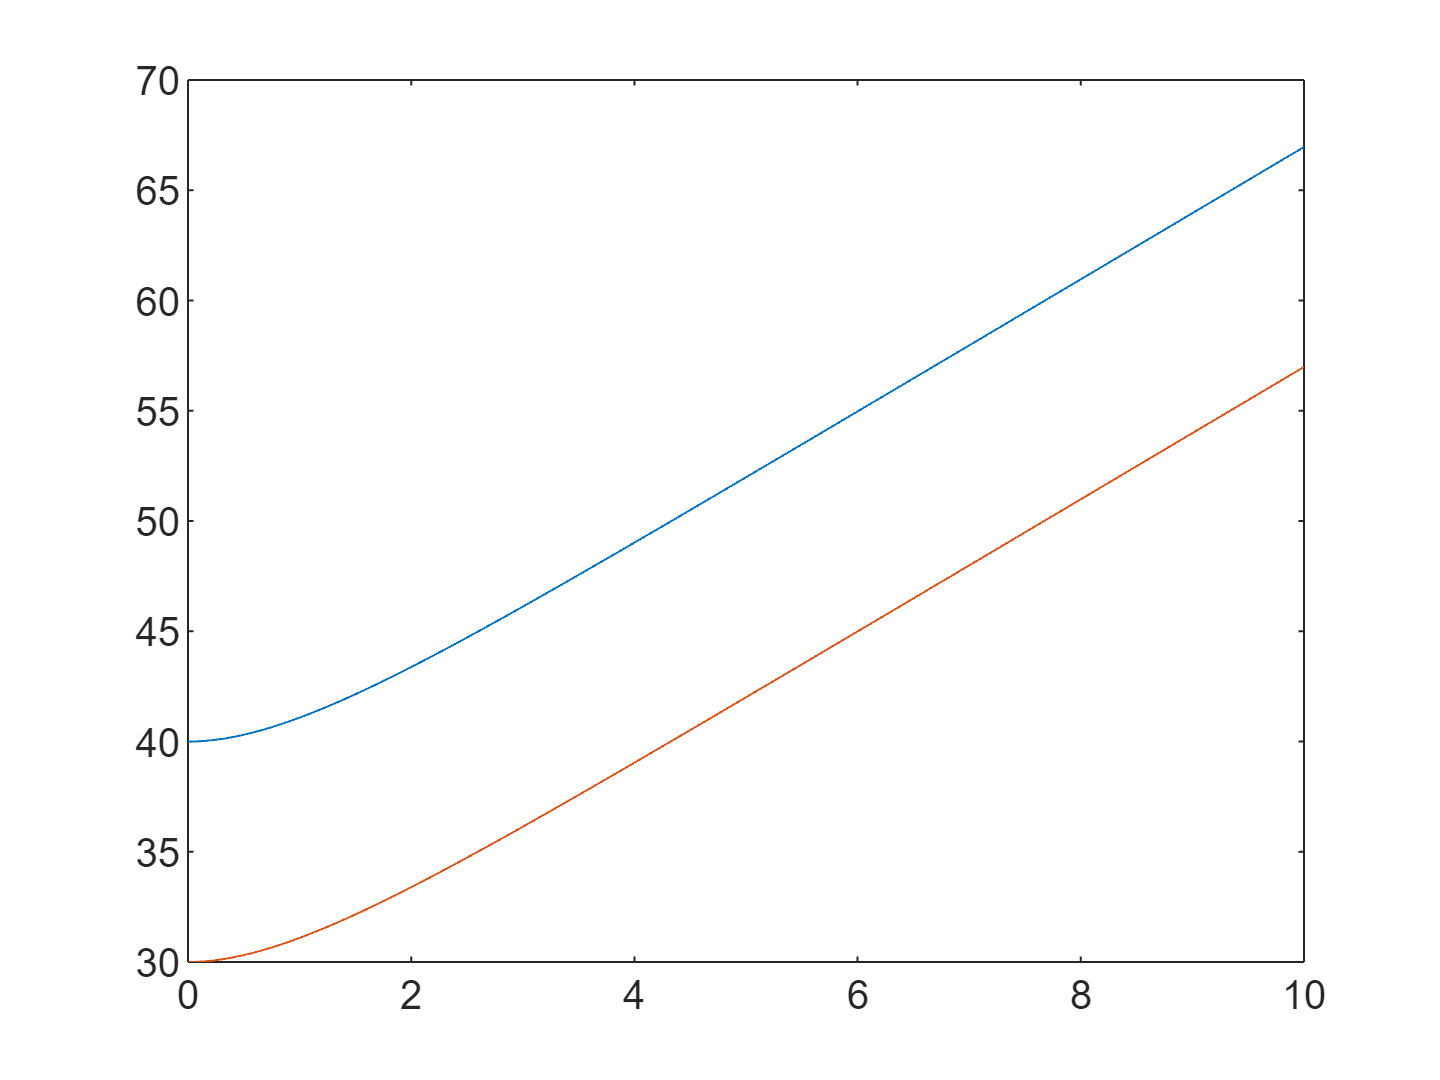

deg= pi/180; % paso de grados a radianes
Estacion= 'T15S4_Control';
open(Estacion)
nPts= 1e3;
tend= 10;
t= linspace(0,tend,nPts)';

% Ángulo inicial y parámetros del sistema
theta0= [40, 30]*deg;
K= [0,0];
B= [1, 1]*1e-2;

% Controladores (proporcional y proporcional de velocidad, derivativo)

Kp= 1e2*diag([1,1]);
Kw= 1e2*diag([1,1]);


% Entrada al sistema
theta1= linspace(theta0(1),theta0(1)+30*deg,nPts)';
theta2= linspace(theta0(2),theta0(2)+30*deg,nPts)';
open_system(Estacion)
sol= sim(Estacion,t,[],[t, theta1, theta2]);
% Salida del sistema
q= sol.yout;
tout= sol.tout;
plot(tout, q/deg)

## Simulador de un robot cartesiano

### Descripción

- Tiene un primer eje prismático y dos ejes rotacionales

- El TCP (*Tool Center Point*) (punto de trabajo del robot) es el extremo del último brazo.

- El robot tiene $3$ grados de libertad y permite posicionar el TCP en la posición $[x,y,z]$ deseada, dentro de los límites que permiten sus brazos y articulaciones. 

- La orientación del TCP siempre apunta hacia abajo en $z$, no se puede modificar esa orientación.

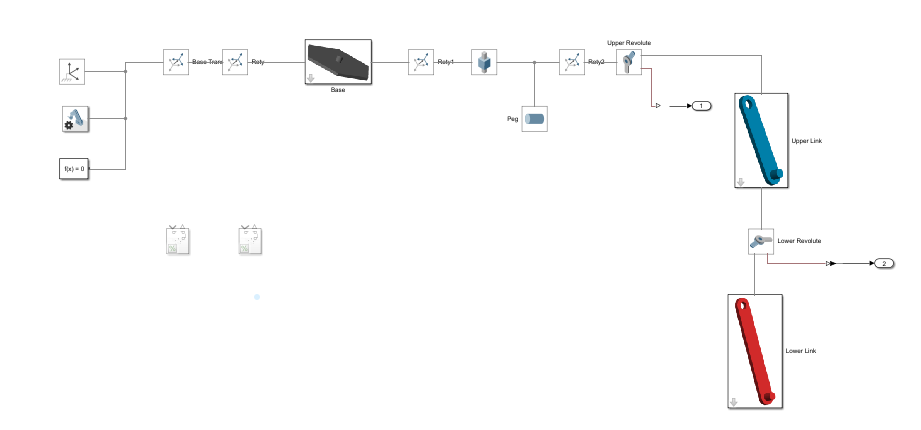

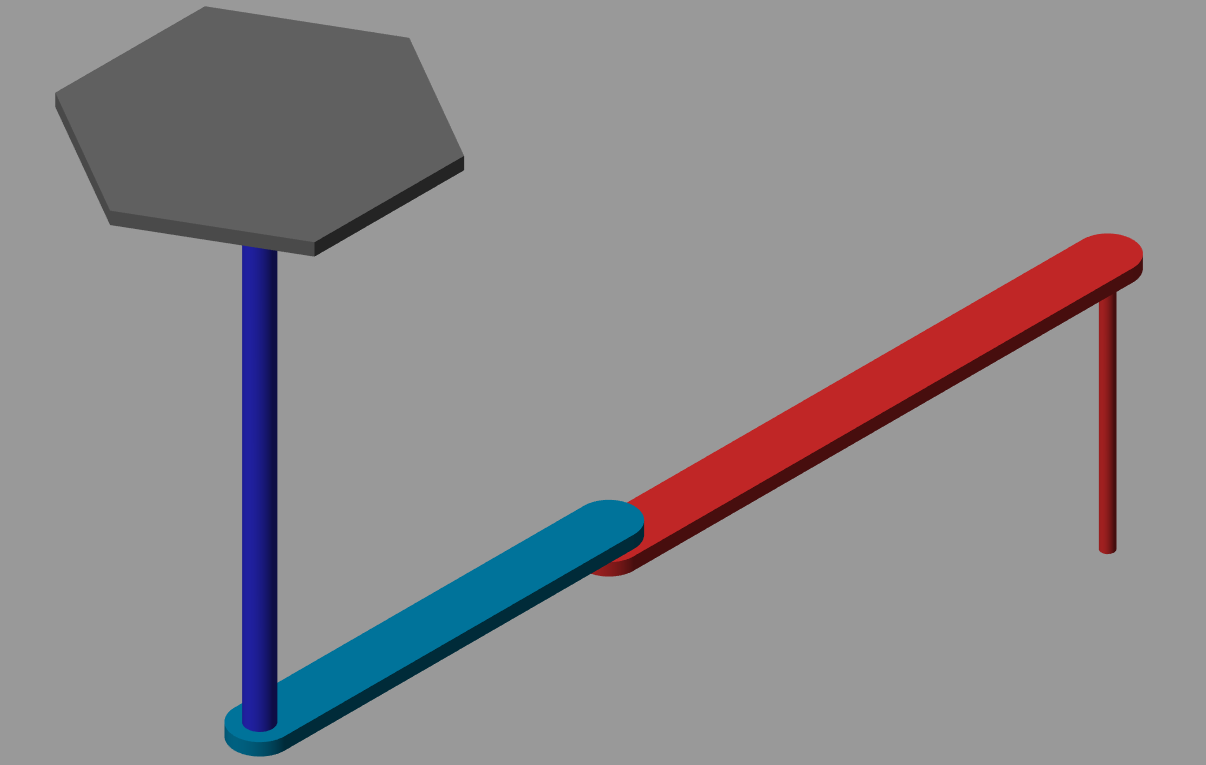



deg= pi/180;
Modelo= 'T15S5_Robot_Cartesiano';

Ry= 90*deg;
K= [0,0,0];
B= [0,0,0];
% longitud del la barra vertical (eje prismático)
L= 200e-3;
p0= -100e-3;
theta0= [0,0]*deg;
nPts= 1e3;

t= linspace(0,10,nPts)';
T= zeros(nPts,1);
p= -100e-3*ones(nPts,1);

sol= sim(Modelo, t);

### Planta dinámica 

- Crear una planta dinámica que tenga como entradas fuezas-par motor

### Planta cinemática 

- Definir una circunferencia de radio $r$ a una distancia $z$ determinada.

### Planta dinámica con realimentación

- Realimentar la planta dinámica para que el sistema siga a una referencia.